Nx = 1024;
Ny = 1024;


% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Cambio
dx =0.1*um;
dy =0.1*um;

waveLength = 650*nm;

% Ditancia Propagación
zlim = Nx*dx^2/waveLength;

z1 = 5 * zlim;
z2 = 1.5 * zlim;

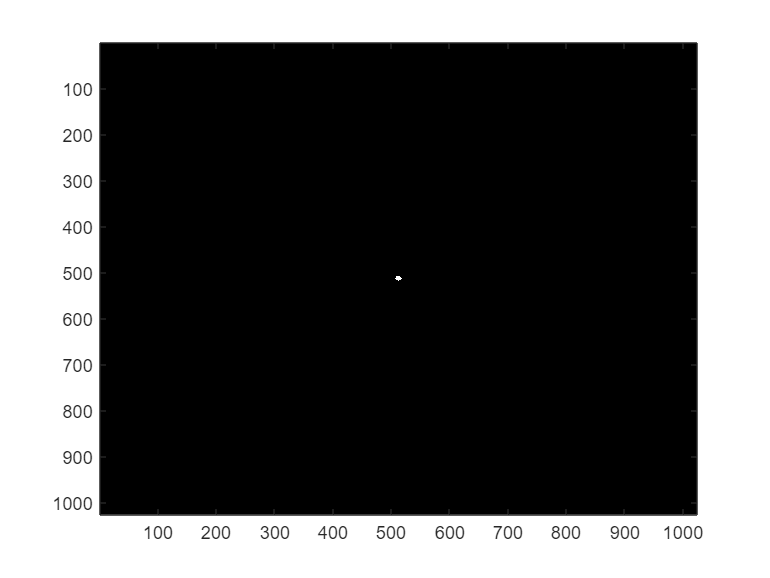

% Transmitancia

radio = 0.5*um/dx;
punto = filtroCircular ([Nx/2 Ny/2],radio,[Ny Nx]);
imagesc(punto)
colormap gray

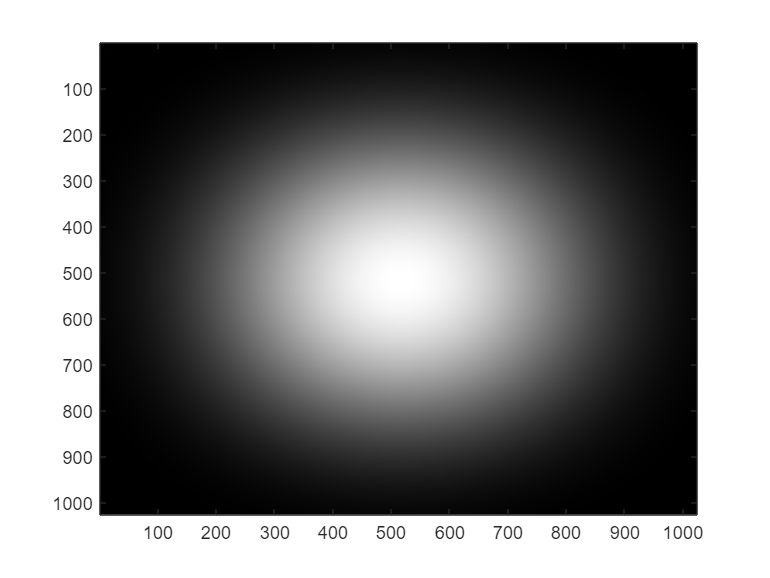

fuentePuntual = transformadaFresnel(punto,dx,dy,z1,waveLength,"dft",false,"zoom",true);
intensidadPunto = imresize(abs(fuentePuntual).^2,[Ny Nx]);
imagesc(intensidadPunto)

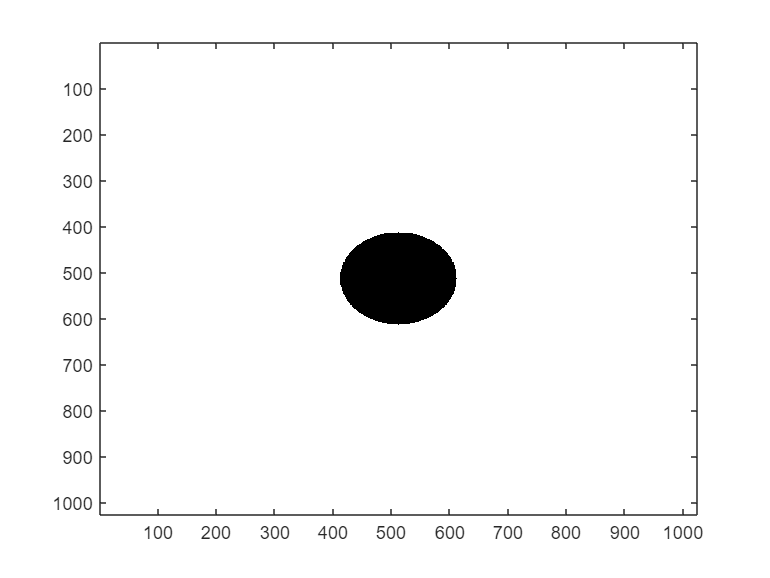

% Transmitancia

radio = 5*um/dx;
obstaculoCircular = ~filtroCircular ([Nx/2 Ny/2],2*radio,[Ny Nx]);
imagesc(obstaculoCircular)
colormap gray

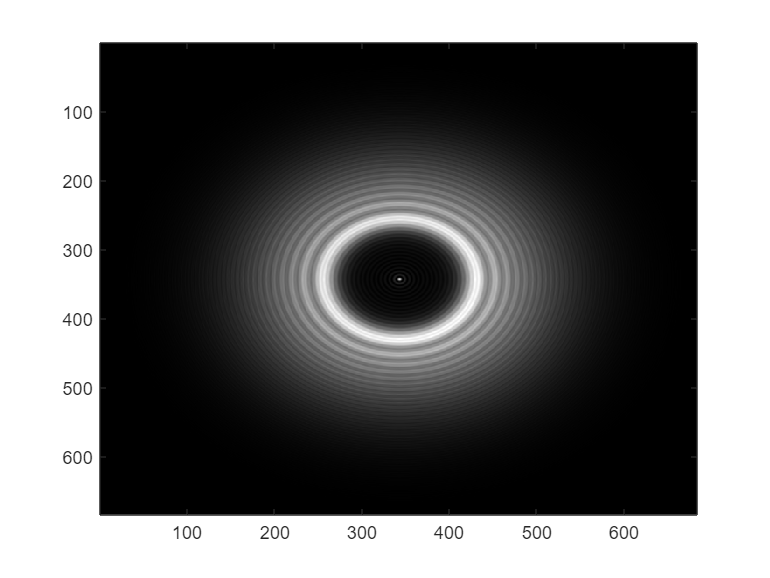

transmitancia = intensidadPunto.*obstaculoCircular;

propagacionArago = transformadaFresnel(transmitancia,dx,dy,z2,waveLength,"dft",false,"zoom",true);
intensidad = abs(propagacionArago).^2;
imagesc(intensidad)